# Karakteristika

Fs = 1;
Ts = 1/Fs;
T = 200;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = ones(1,(T*Fs)+1);
simin = [t',u'];

% open_system("seminar_simulink")
simy = [];
for i = 0:0.1:2.5
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy = [ans.simouty.Data,simy];
end

open_system("seminar_simulink")

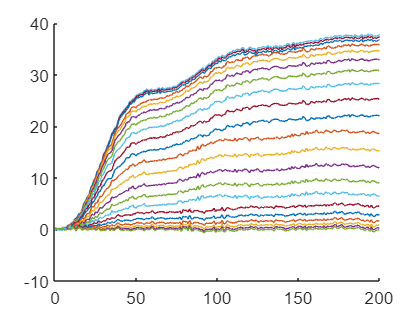

figure;
hold on;
for i = 1:length(simy(1,:))
    plot(t',simy(:,i));
end

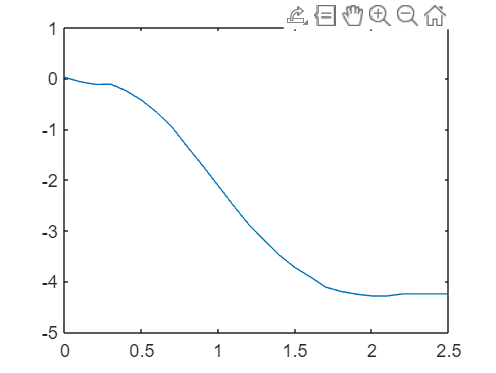

const = [];
for i = 1:length(simy(1,:))
    const = [mean(simy(end-20:end,i)),const];
end
figure
plot(0:0.1:2.5,const)

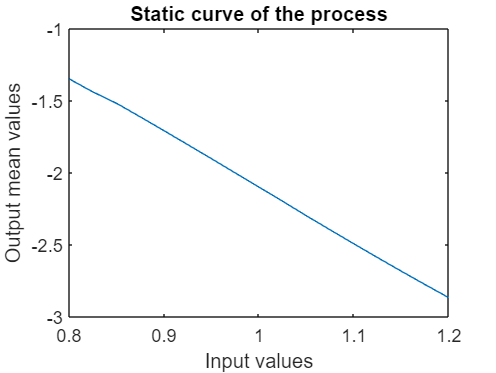

% open_system("seminar_simulink")
simy_short = [];
for i = 0.6:0.025:1.4
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy_short = [ans.simouty.Data,simy_short];
end
const_short = [];
for i = 1:length(simy_short(1,:))
    const_short = [mean(simy_short(end-20:end,i)),const_short];
end
figure
plot(0.6:0.025:1.4,const_short)
xlabel("Input values")
ylabel("Output mean values")
title("Static curve of the process")

open_system("seminar_simulink");

## Frekvenčni Odziv in noise

Fs = 0.0625;
Ts = 1/Fs;
T = 19200;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = zeros(1,(T*Fs)+1);
simin = [t',u'];

% open_system("seminar_simulink");
set_param('seminar_simulink','StopTime',int2str(T));
sim("seminar_simulink");
Noise = ans.simouty.Data;

U_PRBS = 0.6 + prbs(10)*0.8;
U_const = ones(length(t)-length(U_PRBS),1);
simin_PRBS = [U_const;U_PRBS];
simin = [t',simin_PRBS];
% open_system("seminar_simulink");
set_param('seminar_simulink','StopTime',int2str(T));
sim("seminar_simulink");
simy_PRBS = [simin,ans.simouty.Data];

t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.1;
yNoise = Noise(179:end);

t = simy_PRBS(:,1);
u = simy_PRBS(:,2)-1;
y = simy_PRBS(:,3)-19.1;

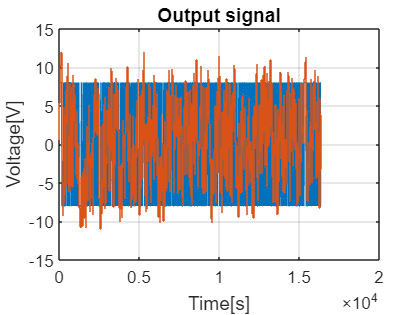

figure
plot(t,u*20)
hold on
stairs(t,y)
xlabel('Time[s]');
ylabel('Voltage[V]');
title('Output signal');
grid on;

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F+F); %frequency vector

## FFT

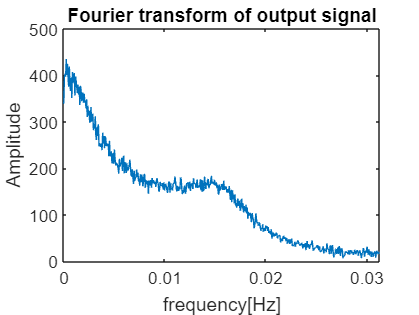

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

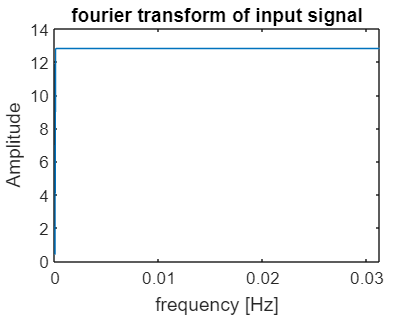


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

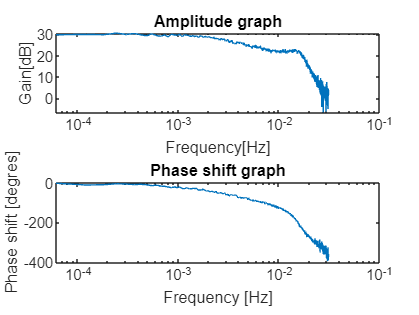

G_jw = FT_output ./ FT_input;
Faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(Faza(1:(end+1)/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

n = 3;
d = 1;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

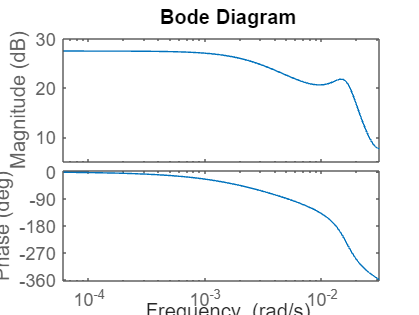


y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
G = tf(numerator', denominator', T);
G.inputdelay = d;


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

figure
bode(G,v);

[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

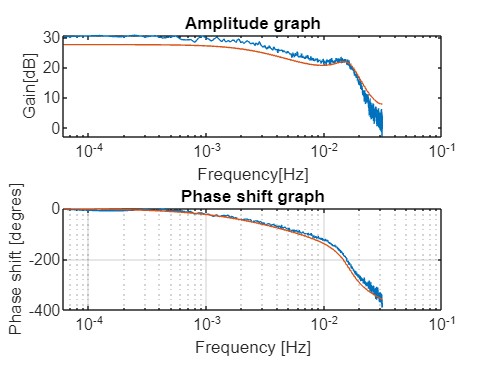

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

## Parametric model 

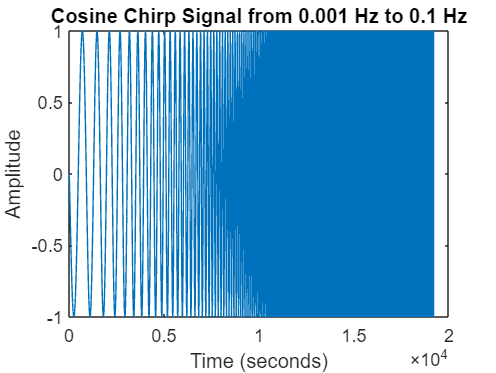

Fs = 10; % Increase the sampling frequency for better resolution
Ts = 1/Fs;
T = 19200;                 % Total time in seconds
t = 0:Ts:T;
% Frequency range
f0 = 0.001;              % Start frequency in Hz
f1 = 0.1;                 % End frequency in Hz

% Generate the cosine chirp signal
% Adding 'phase', pi/2 to generate a cosine instead of a sine wave chirp
signal = chirp(t, f0, T, f1, 'logarithmic', 90); % phase in degrees

% Plot the signal
figure;
plot(t, signal);
title('Cosine Chirp Signal from 0.001 Hz to 0.1 Hz');
xlabel('Time (seconds)');
ylabel('Amplitude');


% Optionally, you can listen to the signal if you want to check its acoustic characteristics
% sound(signal, Fs); % Uncomment this line if you want to listen to the signal

temp = (signal)'+1;
oness = ones(1,6000);
U_true = [oness';temp];
t = 0:Ts:19200 + 600;
simin = [t', U_true];

%v simulinku spremeni čas na 260
% sampling rate pa je 0.01

set_param('seminar_simulink','StopTime',int2str(19200 + 600));
sim("seminar_simulink");
exp_true = [simin,ans.simouty.Data];


t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.1;

tm = exp_true(1:end-6001,1);
um = exp_true(6002:end,2)-1;
ym = exp_true(6002:end,3)-19.1;

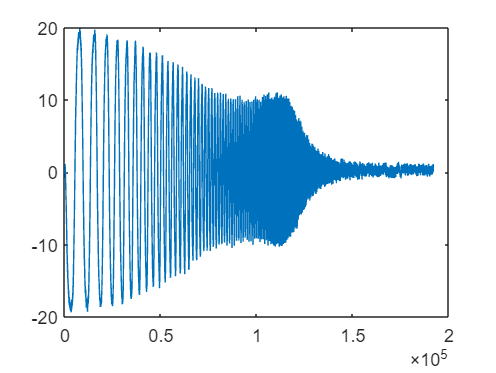

figure
plot(ym)

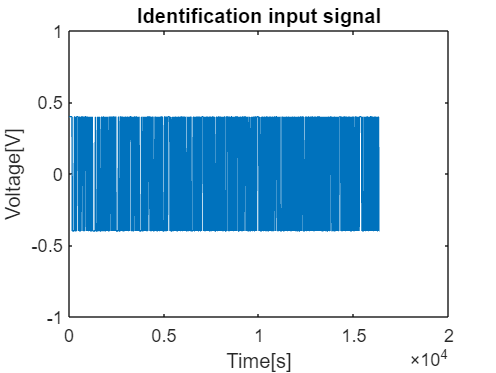

figure
plot(t,u)
% hold on 
% grid on
% stairs(t,y)
ylim([-1 1])
title("Identification input signal")
xlabel("Time[s]")
ylabel("Voltage[V]")

% 
% figure
% plot(tm,-um)
% hold on 
% grid on
% stairs(tm,ym)

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

Nm = length(tm);
Tm = tm(2,1) - tm(1,1);
Fm = 1 / (Nm * Tm);
fmaxm = 1/(2*Tm);
vm = 0:Fm:(fmaxm - Fm); %frequency vector

## FFT

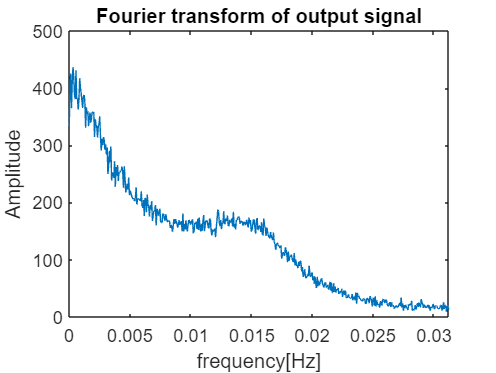

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

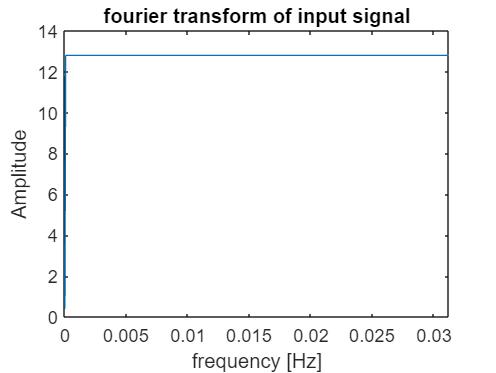


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

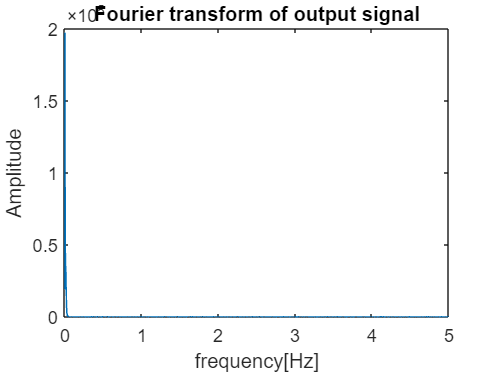


FT_input_m = fft(um);
FT_output_m = fft(ym);

figure;
plot(vm,abs(FT_output_m(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

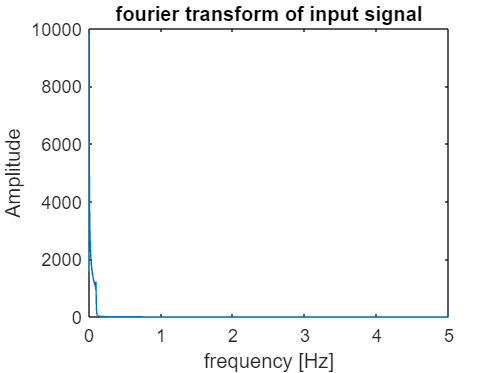


plot(vm,abs(FT_input_m(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

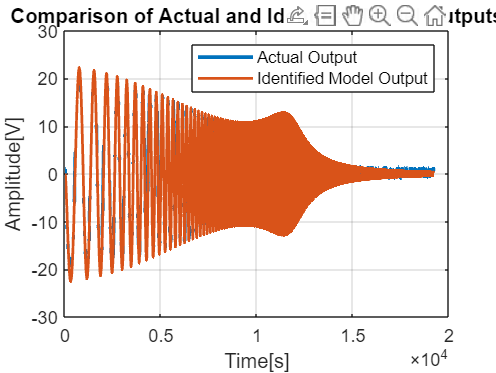

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

T = t(2,1) - t(1,1);

y_short = y((n+d+1):end);
Th = psi \ y_short;
Tmp = T;

numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
G = tf(numerator', denominator', Tmp);
G.inputdelay = d;

figure
G_resampled = d2d(G, 0.1);
% bode(G_resampled,v);
[MAG, PH]=bode(G_resampled, v);
MAG = MAG(:);
PH = PH(:);

% G_resampled.inputdelay = 2
ymm = lsim(G_resampled, um, tm);
figure;
plot(tm, ym, 'LineWidth', 2);
hold on;
plot(tm, ymm, 'LineWidth', 1.5);
xlabel('Time[s]');
ylabel('Amplitude[V]');
legend('Actual Output', 'Identified Model Output');
title('Comparison of Actual and Identified Model Outputs');
grid on;


error = ymm - ym;
std_dev = std(error);
disp(['Standard Deviation of the Error: ', num2str(std_dev)]);

Standard Deviation of the Error: 1.9033


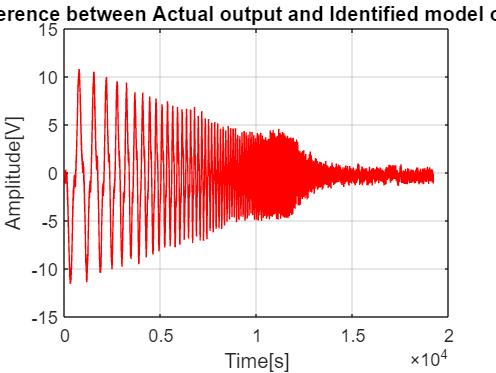

figure
plot(tm, error,"r");
xlabel('Time[s]');
ylabel('Amplitude[V]');
title('Difference between Actual output and Identified model output');
grid on;

% Calculate residuals
y_pred = psi * Th;  % Predicted outputs using the model
residuals = y_short - y_pred;

% Estimate the variance of the residuals
N = size(psi, 1);   % Number of observations
p = size(Th, 1);    % Number of parameters
sigma2 = (residuals' * residuals) / (N - p);

% Calculate covariance matrix of the parameter estimates
Cov_Theta = sigma2 * pinv(psi' * psi);

% Compute standard deviations of the estimates
std_Theta = sqrt(diag(Cov_Theta));

% Display the standard deviations
disp('Standard deviations of the parameters:');

Standard deviations of the parameters:


disp(std_Theta);

    0.0075
    0.0062
    0.0032
    0.0257
    0.0339
    0.0643



## Noise

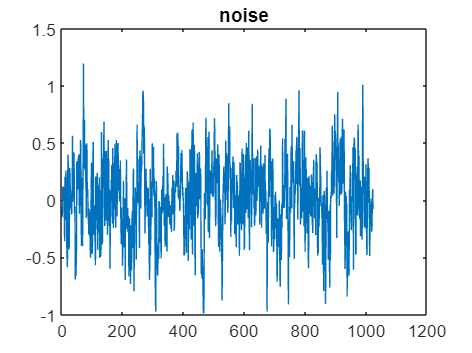

figure
plot(yNoise)
title("noise")


fftNoise = fft(yNoise);
plot(v,abs(fftNoise(1:(end+1)/2)))
title("fourier transformed noise")

hold on

N0 = 65;
N_inf = 12;

wg = 0.003;

%Ng = abs(Noise(wg));
approx = N_inf + ((N0 - N_inf)./sqrt(1 + pow2(v/wg)))

approx =    49.4767   49.3442   49.2112   49.0778   48.9440   48.8097   48.6750   48.5399   48.4044   48.2685   48.1322   47.9955   47.8585   47.7210   47.5833   47.4452   47.3067   47.1680   47.0289   46.8895   46.7498   46.6098   46.4696   46.3291   46.1883   46.0473   45.9060   45.7646   45.6229   45.4810   45.3389   45.1966   45.0541   44.9115   44.7687   44.6257   44.4826   44.3394   44.1961   44.0527   43.9091   43.7655   43.6218   43.4781   43.3342   43.1903   43.0464   42.9025   42.7585   42.6145


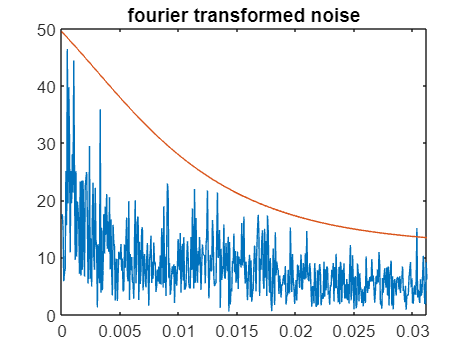

plot(v, approx)

## Standard deviation of the error

d_G = (abs(approx))./abs(FT_output(1:(end+1)/2))'

d_G =     0.1492    0.1256    0.1230    0.1231    0.1214    0.1191    0.1157    0.1287    0.1258    0.1180    0.1258    0.1212    0.1292    0.1284    0.1177    0.1201    0.1183    0.1305    0.1259    0.1240    0.1126    0.1268    0.1367    0.1254    0.1404    0.1262    0.1401    0.1294    0.1244    0.1283    0.1283    0.1231    0.1281    0.1266    0.1446    0.1272    0.1243    0.1244    0.1375    0.1372    0.1484    0.1296    0.1405    0.1444    0.1421    0.1532    0.1370    0.1357    0.1394    0.1460


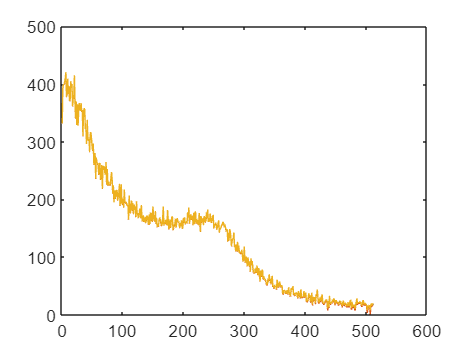


figure
plot(abs(FT_output(1:(end+1)/2)))
hold on
plot(abs(FT_output(1:(end+1)/2)) - d_G')
plot(abs(FT_output(1:(end+1)/2)) + d_G')

## stochastic 

% Initialize parameters
T = t(2,1) - t(1,1);
n = 3; % Order of the system
d=1;
theta = zeros(n*2,1); % Initial parameter guess ([a1, a2, a3, b0, b1, b2])
P = 1000*eye(n*2); % Initial covariance matrix
lambda = 0.98; % Forgetting factor

% Initialize data vectors
phi = zeros(n*2,1); % Regression vector
Y = zeros(length(u),1); % To store estimated output

% Recursive Least Squares estimation
for k = n+1:length(u)
    % Update regression vector
    phi_y = -y(k-1:-1:k-n); % Y part of the regression vector
    phi_u = u(k-n-d+1:k-d); % U part of the regression vector (includes u(k))
    phi = [phi_y; phi_u]; % Combine both parts
    
    % Compute the output estimation
    Y(k) = phi' * theta;
    
    % Update the covariance matrix
    P = (P - (P * (phi * phi') * P) / (lambda + phi' * P * phi)) / lambda;
    
    % Update the parameter estimate
    theta = theta + P * phi * (y(k) - Y(k));
end

% Display estimated parameters
disp('Estimated parameters:');

Estimated parameters:


disp(theta);

   -0.6918
    0.4554
   -0.3639
    1.8177
    7.9821
    2.7957




numerator = theta(n+1:(n*2));
denominator = [1; theta(1:n)];
G_estimated = tf(numerator', denominator', T*2*pi);
G_estimated.inputdelay = d

G_estimated =
 
               1.818 z^2 + 7.982 z + 2.796
  z^(-1) * ------------------------------------
           z^3 - 0.6918 z^2 + 0.4554 z - 0.3639
 
Sample time: 100.53 seconds
Discrete-time transfer function.
Model Properties


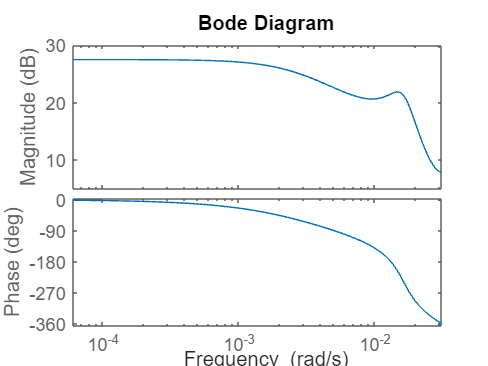

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

figure
bode(G,v);

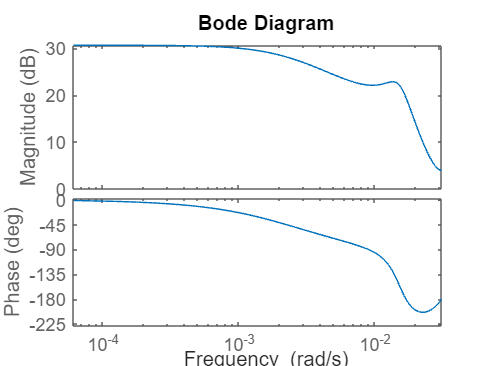

figure
bode(G_estimated,v);

## ortogonal corelation

N = 2

N = 2

i = 1

simin = 1.0e+04 *

         0    0.0001
    0.0152    0.0001
    0.0303    0.0001
    0.0455    0.0001
    0.0606    0.0001
    0.0758    0.0001
    0.0909    0.0000
    0.1061    0.0000
    0.1212    0.0000
    0.1364   -0.0000


y =    -0.2108
   -0.1939
   -0.1939
   -0.1939
   -0.1939
   -0.1939
   -0.1939
   -0.1939
   -0.1939
   -0.1939


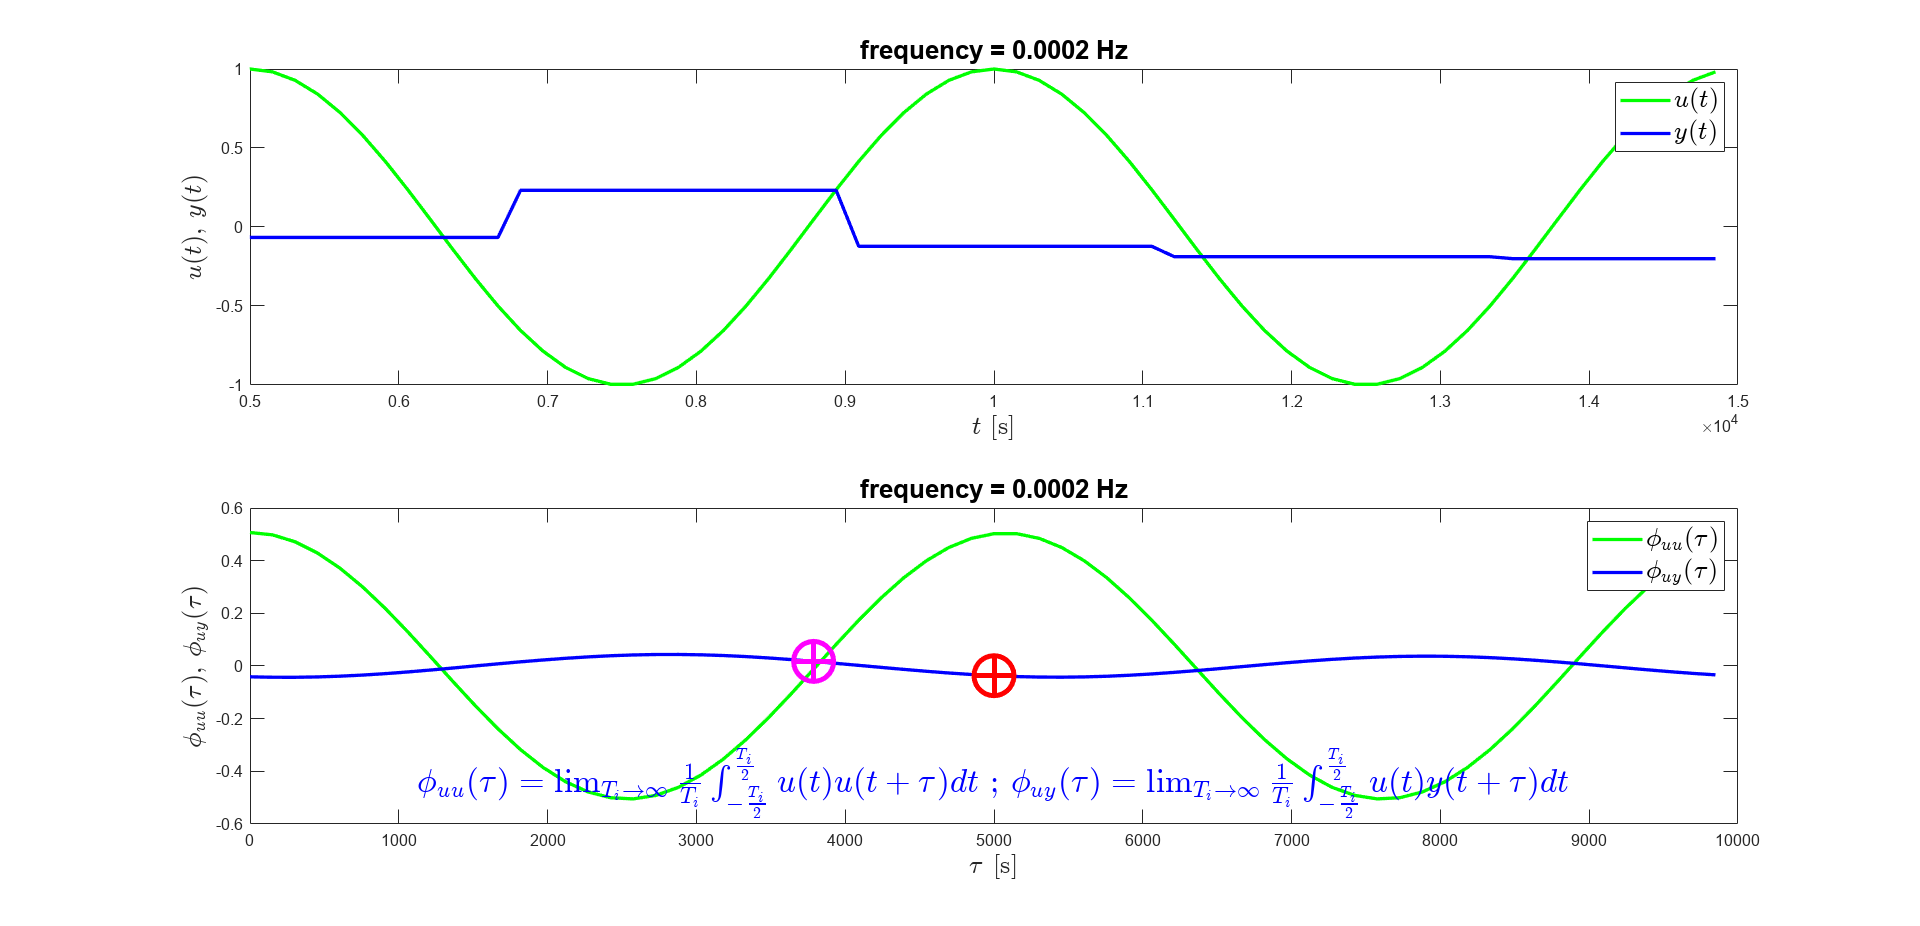

i = 2

simin = 1.0e+04 *

         0    0.0001
    0.0182    0.0001
    0.0363    0.0001
    0.0545    0.0000
    0.0727    0.0000
    0.0908   -0.0000
    0.1090   -0.0001
    0.1272   -0.0001
    0.1453   -0.0001
    0.1635   -0.0001


Simulation aborted

n=100;

% Process model (continuous transfer function numerator and denominator)
b=numerator';
a=denominator';

% Number and values of test frequencies
N = 10;
f=2*logspace(-4,-2,N);

for i=1:N
    i
    % definiramo vhodni signal; casovna os se prilagaja frekvenci
    Perioda = 1/f(i);
    % zacetni cas je vsaj 300 sek, da minejo prehodni pojavi
    t_zacetni = 300;
    Zacetnih_period = ceil(t_zacetni/Perioda);
    % zacetni cas mora biti na zacetku periode
    t_zacetni = Zacetnih_period * Perioda;
    t_koncni = t_zacetni + Stevilo_period_opazovanja(i) * Perioda;
    t=linspace(0,t_koncni,n)';
    %
    % vhodni signal je cosinus
    x=cos(2*pi*f(i)*t);
    %
    % Za izracun bomo rabili se sinus
    x1=sin(2*pi*f(i)*t);
    %
    % Indeksi zacetka in konca prikazanega signala
    ind1 = round(t_zacetni/t(2));
    ind3 = round(t_koncni/t(2));
    % izracunamo izhodni signal in ga zmotimo s sumom
    simin = [t,x]
    Ts = 1/(t(3)-t(2));
    set_param('seminar_simulink','StopTime',int2str(t(end)));
    sim("seminar_simulink");
    y = ans.simouty.Data

    %
    % prikaz vhodnega in izhodnega signala na zaslonu le  za 5 izbranih
    % frekvenc
    if sum([1  13  26  38 N] == i) ~= 0
        %
        % Narisemo vhodni in izhodni signal pri trenutni frekvenci
        figure
        % set(gcf,'Units','normalized', 'Outerposition', [0 0.04 1 0.96]); % poveèamo graf èez cel ekran
        subplot(211)
        hLu = plot(t(ind1:ind3),x(ind1:ind3),'g',t(ind1:ind3),y(ind1:ind3),'b');
        %plot(t(ind1:ind3),x(ind1:ind3),'g',t(ind1:ind3),y(ind1:ind3),'b');
        set(hLu,'linewidth',deb_lin);
        set(gca,'xlim',[t_zacetni t_koncni]);%,'ylim',[-3 3])
        title(['frequency = ',num2str(f(i)),' Hz'],'Fontsize',16)
        xlabel('$t$ [s]','Fontsize',16,'Interpreter','Latex');
        ylabel('$u(t)$, $y(t)$','Fontsize',16,'Interpreter','Latex');
        l = legend(hLu,'$u(t)$','$y(t)$');
        set(l,'Fontsize',16,'Interpreter','Latex', 'AutoUpdate','off');
        %
        % Ceprav za izracun ni potrebno izracunati celotnih korelacijskih
        % funkcij, jih tu za ilustracijo eliminacije suma prikazimo:
        xx=xcorrp(x(ind1:ind3),x(ind1:ind3));
        xy=xcorrp(x(ind1:ind3),y(ind1:ind3));
        %
        % Ilustrativni prikaz avtokorelacijske funkcije vhoda
        % in krizne korelacije med vhodom in izhodom
        %
        %      Vpliv suma postane zanemarljiv.
        n4=ind3-ind1;
        subplot(212);
        hLu =  plot(t(1:n4),xx(1:n4),'g',t(1:n4),xy(1:n4),'b');
        %plot(t(ind1:ind3),x(ind1:ind3),'g',t(ind1:ind3),y(ind1:ind3),'b');
        set(hLu,'linewidth',deb_lin);
        set(gca,'xlim',[0 t_koncni-t_zacetni]);%,'ylim',[-1.5 1.5])
        title(['frequency = ',num2str(f(i)),' Hz'],'Fontsize',16)
        xlabel('$\tau$ [s]','Fontsize',16,'Interpreter','Latex');
        ylabel('$\phi_{uu}(\tau)$, $\phi_{uy}(\tau)$','Fontsize',16,'Interpreter','Latex');
        l = legend(hLu,'$\phi_{uu}(\tau)$','$\phi_{uy}(\tau)$');
        set(l,'Fontsize',16,'Interpreter','Latex', 'AutoUpdate','off');
        %
        % vzorcenje realne komponente korelacijskih funkcij (samo za prikaz na
        % zaslonu, racuna se drugace
        Stevilo_period = floor(t_koncni/Perioda)-1;
        t_real = (Stevilo_period - Zacetnih_period)*Perioda;
        % izracun indeksa az vorcenje realne komponente - pri polni periodi
        ind_real = round(t_real/t(2))+1;
        % izracun indeksa az vorcenje imaginarne komponente - pri 3/4
        % periode
        t_imag = (Stevilo_period - Zacetnih_period - 1/4)*Perioda;
        ind_imag = round(t_imag/t(2))+1;
        %
        % Prikazemo tocko na koncu in na 3/4 periode, ki sta realni in
        % imaginarni del frekvenènega odziva
        hold on
        h_Re = plot(t(ind_real),xy(ind_real),'ro');
        set(h_Re,'Markersize',24,'linewidth',3);
        h_Re = plot(t(ind_real),xy(ind_real),'r+');
        set(h_Re,'Markersize',24,'linewidth',3);
        %
        h_Im = plot(t(ind_imag),xy(ind_imag),'mo');
        set(h_Im,'Markersize',24,'linewidth',3);
        h_Im = plot(t(ind_imag),xy(ind_imag),'m+');
        set(h_Im,'Markersize',24,'linewidth',3);
        %
        besedilo4a = ['$\phi_{uu}(\tau)  = \lim_{T_i\rightarrow \infty}',...
            '\frac{1}{T_i} \int_{-\frac{T_i}{2}}^{\frac{T_i}{2}} u(t)u(t+\tau)dt$'];
        besedilo4b = ['$\phi_{uy}(\tau)  = \lim_{T_i\rightarrow \infty}',...
            '\frac{1}{T_i} \int_{-\frac{T_i}{2}}^{\frac{T_i}{2}} u(t)y(t+\tau)dt$'];
        hh2 = text(0.5, 0.02, [besedilo4a,'  ;  ',besedilo4b],'Units','normalized');
        set(hh2, 'Interpreter','Latex','Color',[0 0 1],'Fontsize',20, ...
            'VerticalAlignment','bottom','HorizontalAlignment','center');
        % pocakamo da si ogledamo eno frekvenco
        gca_pos = get(gca,'Position');
        hh = text(1+(1-gca_pos(1)-gca_pos(3)), -2*gca_pos(2), 'Press any key', ...
            'Units','normalized', 'HorizontalAlignment','right', 'VerticalAlignment','bottom', 'FontSize',14, 'Color',[0 0.5 0]);
        pause
        delete(hh);
    end
    % ali naredimo detrend meritve izhodnega signala
    %
    % izracun re. in imag. komponente frekvencnega odziva
    %
    % Formule: 3.49 in 3.51 pomenijo 2 krat srednja vrednost produktov
    re=y(ind1:ind3)'*x(ind1:ind3)*2/(ind3-ind1);
    im=-y(ind1:ind3)'*x1(ind1:ind3)*2/(ind3-ind1);
    ampl(i)=sqrt(re^2+im^2);
    faza(i)=atan2(im,re);
end

## moje

n=1000;
% Process model (continuous transfer function numerator and denominator)
% Number and values of test frequencies
N = 50;
f=3*logspace(-4,-2,N);
Stevilo_period_opazovanja = round(linspace(2,30,N));
ampl = nan(1,N); faza = nan(1,N);
for i=1:N
    % definiramo vhodni signal; casovna os se prilagaja frekvenci
    Perioda = 1/f(i);
    % zacetni cas je vsaj 300 sek, da minejo prehodni pojavi
    t_zacetni = 300;
    Zacetnih_period = ceil(t_zacetni/Perioda);
    % zacetni cas mora biti na zacetku periode
    t_zacetni = Zacetnih_period * Perioda;
    t_koncni = t_zacetni + Stevilo_period_opazovanja(i) * Perioda;
    t=linspace(0,t_koncni,n)';
    %
    % vhodni signal je cosinus
    x=1+(cos(2*pi*f(i)*t)*0.2);
    %
    % Za izracun bomo rabili se sinus
    x1=1+(sin(2*pi*f(i)*t)*0.2);
    %
    % Indeksi zacetka in konca prikazanega signala
    ind1 = round(t_zacetni/t(2));
    ind3 = round(t_koncni/t(2));
    % izracunamo izhodni signal in ga zmotimo s sumom
    simin = [t,x];
    Ts = (t(3)-t(2));
    set_param('seminar_simulink','StopTime',int2str(t(end)));
    sim("seminar_simulink");
    y = ans.simouty.Data;

    re=((y(ind1:ind3)-20))'*((x(ind1:ind3)-1)*5)*2/(ind3-ind1);
    im=-((y(ind1:ind3)-20))'*((x1(ind1:ind3)-1)*5)*2/(ind3-ind1);
    ampl(i)=sqrt(re^2+im^2);
    faza(i)=atan2(im,re);
end 
faza=unwrap(faza);

## plot

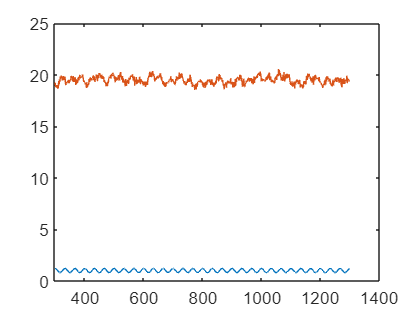

figure;
plot(t(ind1:ind3),x(ind1:ind3))
hold on
plot(t(ind1:ind3),y(ind1:ind3))

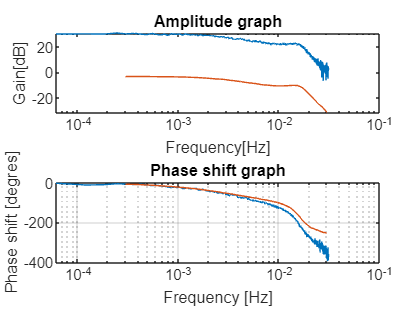

figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(f,20*log10(ampl))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(Faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(f,180/pi*faza)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")